# **ARXDE: Identifying Gradients in Fluid Physics with Autoregressive Modeling**

## Hanfeng Zhai & Timonthy Sands, [Adaptive and Learning Systems](https://classes.cornell.edu/browse/roster/FA20/class/MAE/6280)

*Sibley School of Mechanical and Aerospace Engineering, Cornell University*

***Website***: [hanfengzhai.net/ARXDE](https://hanfengzhai.net/ARXDE)

***Prerequisite***: `MATLAB R2021A`, `COMSOL Multiphysics`

clear all;close all;clc
load('FluidData.mat')

## **Generate Time Histories of Data for ARXDE with fluid mechanics **

Input $u$ $\Rightarrow$ could be anything in the physics field, i.e., velocity, pressure, etc.

Output $\mathcal{G}$ $\Rightarrow$ the gradients of certain physics field, i.e., $\nabla_x u,\ \nabla_{xx}u,\ \nabla_{xy}u, $ etc.

***Discretization assumptions: ***

[First derivative: 1st order]: $\mathcal{G} = {\partial u \over \partial x }= {u_{i} - u_{i-1} \over \Delta x}$; 

[First derivative: 2nd order]: $\mathcal{G} = {\partial u \over \partial x}= {3u_{i} - 4u_{i-1} + u_{i-2}\over 2\Delta x}$;

[Second derivative: 1st order] $\mathcal{G} = {\partial^2 u \over \partial x^2 }= {u_{i} - 2u_{i-1} + u_{i-2} \over \Delta x^2}$; 

[Second derivative: 2nd order] $\mathcal{G} = {\partial^2 u \over \partial x^2 }= {2u_{i} - 5u_{i-1} + 4u_{i-2} - u_{i-3}\over \Delta x^2}$.

ndata=3520;   % Spatial data discretized to 3520 meshes
u = uu(:,50);
save input u	%input Gaussian noise N(0,1) and save for all analysis
%load input u;		%Load previously saved random input
% Loop over the Model 1 to generate output y(t):
n=3; m=n-1; %Forced by Hutchins modification of [Astrom] text problem setup {deg(B(q)=m+1}
u1=[zeros(n,1);u];y1=[zeros(n,1);zeros(ndata,1)];%delay input vector and initialize vector to start at n+1
for t=n+1:ndata+n    %Create time histories via loop
    y1(t,1)= (3*u1(t,1) - 4*u1(t-1,1) + 2*u1(t-2,1))/2;
    %1st derivative, 1st order: (u1(t,1) - u1(t-1,1));
    %1st derivative, 2nd order: (3*u1(t,1) - 4*u1(t-1,1) + 2*u1(t-2,1))/2;
    %2nd derivative, 1st order: (u1(t,1) - 2*u1(t-1,1) + u1(t-2,1));
    %2nd derivative, 2nd order: (2*u1(t,1) - 5*u1(t-1,1) + 4*u1(t-2,1)) - u1(t-3,1);
end
utrue=u(:,1);ytrue=y1(n+1:ndata+n,1);time = [0:(max(size(ytrue))-1)];%Create arrays to plot


## Generate the Figures for input and output

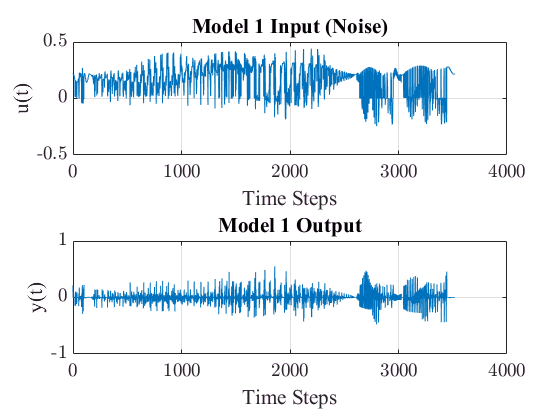

figure(1);subplot(2,1,1);plot(time,utrue);title('Model 1 Input (Noise)','fontsize',16,'fontname','times');set(gca,'fontsize',14,'LineWidth',0.5);
ylabel('u(t)','fontsize',16,'fontname','times');xlabel('Time Steps','fontsize',16,'fontname','times');grid;%axis([0, 100, -10, 10]);
subplot(2,1,2);plot(time,ytrue);title('Model 1 Output','fontsize',16,'fontname','times');set(gca,'fontsize',14,'LineWidth',0.5);
ylabel('y(t)','fontsize',16,'fontname','times');xlabel('Time Steps','fontsize',16,'fontname','times');grid;%axis([0, 100, -10, 10]);

## Build up the Autoregressive model

ans = 0

MSE = 0.23589, with nstar= 1


ans = 0

MSE = 0.23823, with nstar= 2


ans = 0

MSE = 0.2385, with nstar= 3


ans = 0

MSE = 0.23436, with nstar= 4


ans = 0

MSE = 0.23452, with nstar= 5


ans = 0

MSE = 0.23446, with nstar= 6


ans = 0

MSE = 0.23379, with nstar= 7


ans = 0

MSE = 0.23423, with nstar= 8


ans = 0

MSE = 0.23309, with nstar= 9


ans = 0

MSE = 0.23362, with nstar= 10


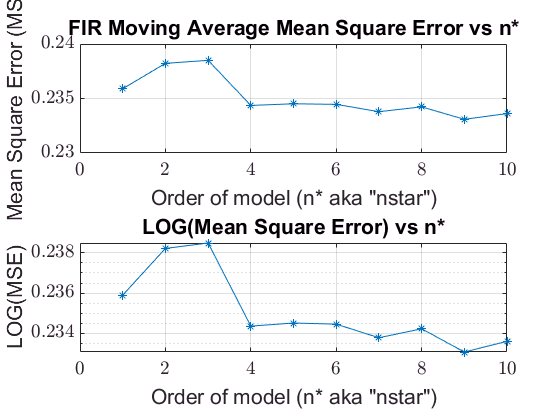

clear y1 u1 n m;  
n0=0;nEnd=10;  m0=1;mEnd=10; % Outer Loop for n & Inner loop for m (Set n0=0 for FIR, set n>0 for Transfer Function)
if n0 > 0       %Execute this loop for Transfer Function model (AUTOREGRESSIVE Moving Average)
    for n = n0:nEnd;    %Outer Loop for number of Autogressive outputs to include
        for m = 1:n     %Inner Loop for number of Moving Average inputs to include
            PHI=[]; nstar=n+m;      % Initialize PHI & nstar
            for tt = 1:ndata % Innermost loop for number of time samples
                theta=[zeros(nstar,1)];       % Initialize [Theta]
                y1=[zeros(n,1);ytrue]; u1=[zeros(m,1);utrue]; %Delay input & output vectors
                PHI(tt,:)=[flipud(y1(tt:tt+n-1,1))' flipud(u1(tt:tt+m-1,1))']; %Form [PHI]
            end             % end of Innermost loop for number of time samples
            thetahat=pinv(PHI'*PHI)*PHI'*ytrue; %Calculate estimate using Batch Least Squares
            yhat=PHI*thetahat;      % Calculate estimated output using theta hat
            mse(m,n)=(ytrue-yhat).^2%sum((ytrue-yhat)'*(ytrue-yhat))/(101-(n+m));   %Mean Square Error
        end                 % end of Inner Loop for number of Moving Average inputs to include
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%                       Plot Mean Square Error vs. nstar                       %%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        figure(2);subplot(2,1,1);plot(n+1:nstar,mse(1:nstar-n,n),'-*');hold on; %Leave hold on to add lines to plot via Outer Loop
        set(gca,'fontsize',14,'LineWidth',0.5);axis([0,20,0,0.00025]);
        text(4,1.7e-4,'n=1 (only 1 output) not depicted.  MSE(n=1)~0.05','fontsize',14)
        title('Mean Square Error vs n*');ylabel('Mean Square Error (MSE)');xlabel('Order of model (n* aka "nstar")');
        
        figure(2);subplot(2,1,2);semilogy(n+1:nstar,mse(1:nstar-n,n),'-*');hold on; %Leave hold on to add lines to plot via Outer Loop
        set(gca,'fontsize',14,'LineWidth',0.5);
        title('LOG(Mean Square Error) vs n*');ylabel('Mean Square Error (MSE)');xlabel('Order of model (n* aka "nstar")');        
        
    end             % End Outer Loop for number of Autogressive outputs to include
    hold off;grid;        %Stop adding lines to MSE plot

    else    %Execute this loop for FIR/Transverse model (NON-AUTOREGRESSIVE Moving Average)
    for m = m0:mEnd,
        PHI=[];                         % Defines empty regression matrix (PHI)
        for tt = 1:ndata
            % size parameter vector: 
            % theta=[a1; a2; ...an; b1; b2; ...bm]
            theta=[zeros(m,1)];             % Defines parameter vector(theta)of zeros
            % size the regression vector:
            % phi(t-1)=[-y(t-1), -y(t-2),..., -y(t-n), u(t+m-n), u(t+m-n-2,...,u(t-n)]
            u1=[zeros(m,1);utrue];        %augments input vector with delay (m)
            PHI(tt,:)=flipud(u1(tt:tt+m-1,1))';
            %PHI=[PHI; phiT];
        end          % end of data loop
        thetahat=inv(PHI'*PHI)*PHI'*ytrue;0
        yhat=PHI*thetahat;
        err=ytrue-yhat;
        mse(m,1)=sum(err'*err)/(101-m);
        disp(['MSE = ',num2str(mse(m,1)),', with nstar= ',num2str(m)])
        
    end
    
      figure(2);subplot(2,1,1);    plot((m0:mEnd),mse,'-*'); set(gca,'fontsize',14,'LineWidth',0.5);grid;
    title('FIR Moving Average Mean Square Error vs n*');ylabel('Mean Square Error (MSE)');xlabel('Order of model (n* aka "nstar")');
    
    figure(2);subplot(2,1,2);semilogy((m0:mEnd),mse,'-*');hold on; %Leave hold on to add lines to plot via Outer Loop
    set(gca,'fontsize',14,'LineWidth',0.5);grid;
    title('LOG(Mean Square Error) vs n*');ylabel('LOG(MSE)');xlabel('Order of model (n* aka "nstar")');        
end         % end of if-else loop  

## Save the data for contour plot

X2 = [X(:,1),X(:,2)];
[xx1,yy1,zz1]=griddata(X2(:,1),X2(:,2),yhat,linspace(0,10,100),linspace(0,10,100)','v4');
[xx2,yy2,zz2]=griddata(X2(:,1),X2(:,2),ytrue,linspace(0,10,100),linspace(0,10,100)','v4');
[xx3,yy3,zz3]=griddata(X2(:,1),X2(:,2),utrue,linspace(0,10,100),linspace(0,10,100)','v4');
[xxbench,yybench,zzbench]=griddata(X2(:,1),X2(:,2),vv(:,50),linspace(0,10,100),linspace(0,10,100)','v4');

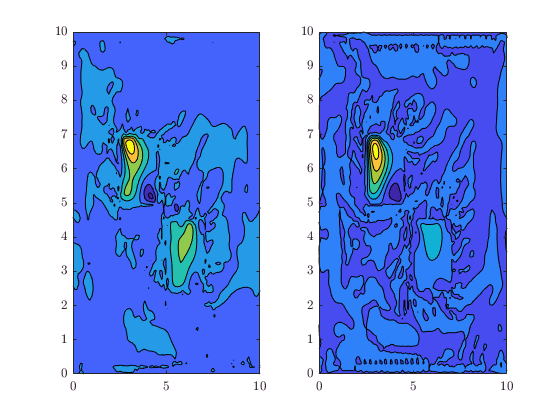

subplot(1,2,1)
contourf(xx1,yy1,zz1);
subplot(1,2,2)
contourf(xx2,yy2,zz2);

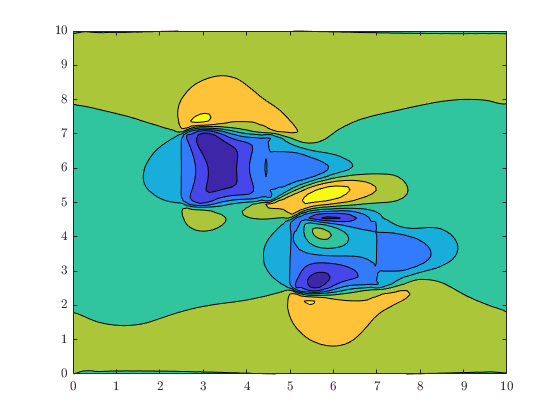

figure()
contourf(xx3,yy3,zz3);

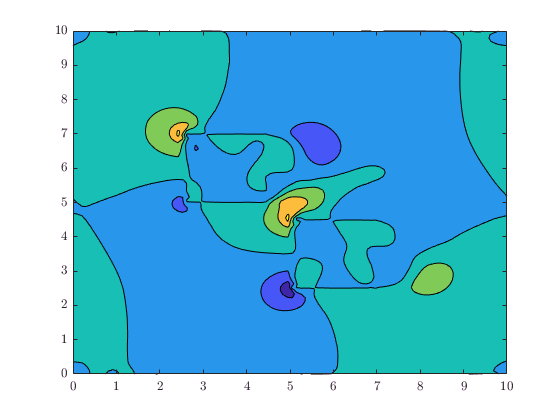

figure
contourf(xxbench,yybench,zzbench);

computime = cputime

computime = 903.2031

## Save the useful data per specific program and clear the rest

x1_12 = xx1; x2_12 = xx2; %x3_12 = xx3;
y1_12 = yy1; y2_12 = yy2; %y3_12 = yy3;
z1_12 = zz1; z2_12 = zz2; %z3_12 = zz3;
cpu_12 = computime;
mse_12 = mse;
clearvars -except x1_12 x2_12 y1_12 y2_12 z1_12 z2_12 cpu_12 mse_12